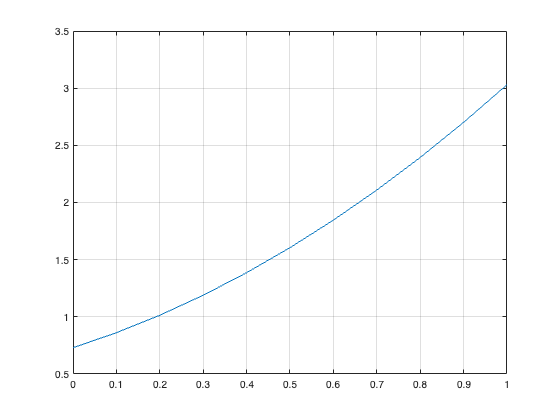

Fr = 1.0;
bw = 0:0.1:1.0;

Frc = zeros(size(bw));
C_D = zeros(size(bw));
lambda_s = zeros(size(bw));

Fr_Frc = zeros(length(Frc) * length(bw), length(bw));

for x = 1:length(bw)
    [C_D(x), lambda_s(x), Frc(x)] = TsunamiParametersFoster(bw(x));
    for f = 1:length(Fr)
        Fr_Frc(f,x) = Fr(f) >= Frc(x);
    end
end


plot(bw,lambda_s)
grid on


% plot(bw, Frc)

% disp([Fr', Fr_Frc])

